**Федеральное агентство железнодорожного транспорта**

Федеральное государственное бюджетное образовательное учреждение

высшего образования

«**Петербургский** **государственный университет путей сообщения Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

­­­­­­­­­­­­––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––

Факультет «Транспортные и энергетические системы» 

Кафедра «Электрическая тяга»

**ОТЧЁТ**

**по лабораторной работе №1**

**«**Исследование однофазного неуправляемого двухполупериодного  выпрямителя**»**

**Вариант №4**

Выполнили:

студенты гр. ПС-003 

Дулепов И.Г. 

Минина А.С.

Проверил:

Сычугов А.Н.

Санкт-Петербург

2024

1.Цель работы - Исследование на компьютерной модели однофазного неуправляемого  двухполупериодного выпрямителя при работе на активно-индуктивную  нагрузку. 

2. Содержание работы Исследование внешней и энергетических характеристик однофазного  двухполупериодного выпрямителя при работе на активно-индуктивную  нагрузку.

3. Задание исходных данных:

Задаём параметры источника напряжения

source.voltage = 220;
source.freq = 100;

Задаём параметры трансформатора

transparam.power = 200 * 10^3;
transparam.volt1wing = 220;
K_T = 1;
transparam.volt2wing = transparam.volt1wing * K_T;

Задаём параметры нагрузки

load.Res = 1;
load.Ind = load.Res * 0.01;

4. Подготавливаем массивы для снятия параметров измерений в таблицу

U_1max = [];
f_1 = [];
L_n = [];
R_n = [];
I_n = [];
U_n = [];
I_1max = [];
Phi = [];
U_VDmax = [];
I_VDmax = [];
S_1 = [];
P_1 = [];
P_n = [];

5. Запускаем модель 10 раз с шагом изменения сопротивления 1 Ом, добавляем значения в вышесозданные массивы каждую итерацию, рассчитываем параметры по формулам:


$$S_{1}(1) = \frac {U_{1max} \cdot I_{1max}}  {2} $$



$$P_{1}(1) = S_{1}(1) \cdot cos(\phi)$$



$$P_н = U_н \cdot I_н$$


for loadRes = 1:1:3
    load.Res = loadRes;
    R_n(end+1) = load.Res;
    load.Ind = load.Res * 0.01;
    L_n (end+1)= load.Ind(end, 1);
        for sourcevoltage = source.voltage
        U_1max(end+1) = sourcevoltage(end, 1);
        end
            for sourcefreq = source.freq
            f_1(end+1) = sourcefreq(end, 1);
            end
    %open('ЛР 1 комп.моделирование\z\lab1dulepovMinina2.slx')
    sim('ЛР 1 комп.моделирование\z\lab1dulepovMinina2.slx');
    I_n(end+1) = loadCurrent(end, 1);
    U_n(end+1) = loadVoltage(end, 1);
    I_1max(end+1) = max(sourceCurrent(end, 1));
    Phi(end+1) = sourcePhase(end, 1);
    U_VDmax(end+1) = max(VoltageVDmax(end, 1));
    I_VDmax(end+1) = max(CurrentVDmax(end, 1));
    S_1(end+1) = U_1max(loadRes) * I_1max(loadRes)/2;
    %P_1(end+1) = S_1(loadRes)*cos(Phi(loadRes)*pi/180);
    %P_n(end+1) = U_n(loadRes) * I_n(loadRes);  
    end

T = table(U_1max.', f_1.',R_n.',L_n.',I_n.', U_n.', I_1max.', Phi.',U_VDmax.', I_VDmax.',S_1.');
T.Properties.VariableNames = ["U_1max","f_1","R_n","L_n","I_n", "U_n", "I_1max", "Phi","U_VDmax", "I_VDmax","S_1"];
disp(T);

    U_1max    f_1    R_n    L_n      I_n       U_n      I_1max      Phi      U_VDmax     I_VDmax       S_1  
    ______    ___    ___    ____    ______    ______    ______    _______    _______    __________    ______

     220      100     1     0.01    128.95    129.02       165    -6.2351       2        0.0032296     18150
     220      100     2     0.02    66.215    132.43    84.683    -5.0205       2       0.00031582    9315.1
     220      100     3     0.03    44.551    133.65    56.964     -4.141       2       0.00057461      6266



6. Заносим результаты моделирования в таблицу 

%T = table(U_1max.',f_1.',L_n.', R_n.', I_n.', U_n.', I_1max.', Phi.',U_VDmax.', I_VDmax.', S_1.', P_1.', P_n.');
%T.Properties.VariableNames = ["U_1max",,"L_n", "R_n", "I_n", "U_n", "I_1max", "Phi","U_VDmax", "I_VDmax", "S_1", "P_1", "P_n"];
%disp(T);

7. Строим осциллограммы мгновенных напряжений и токов (для сопротивления нагрузки 1, 5 и 10 Ом) :

Осцилограммы тока питания, нагрузки и напряжения на нагрузке (для сопротивления нагрузки 1 Ом) :

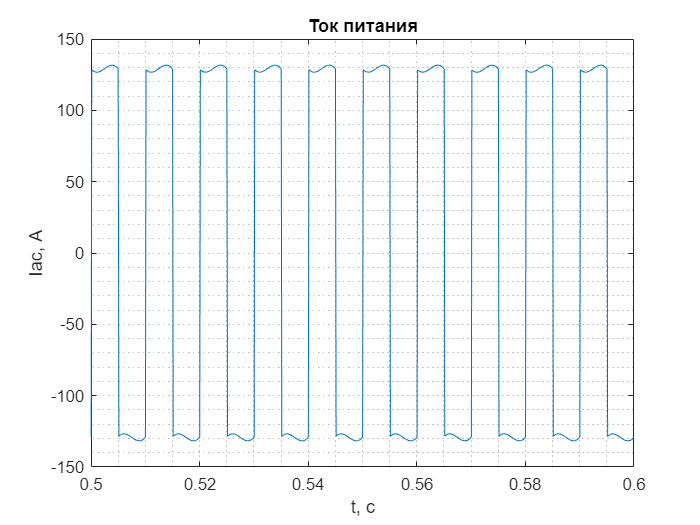

for R = 1
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeACRL{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iac, А');
title('Ток питания');
xlim([0.5 0.6]);
end

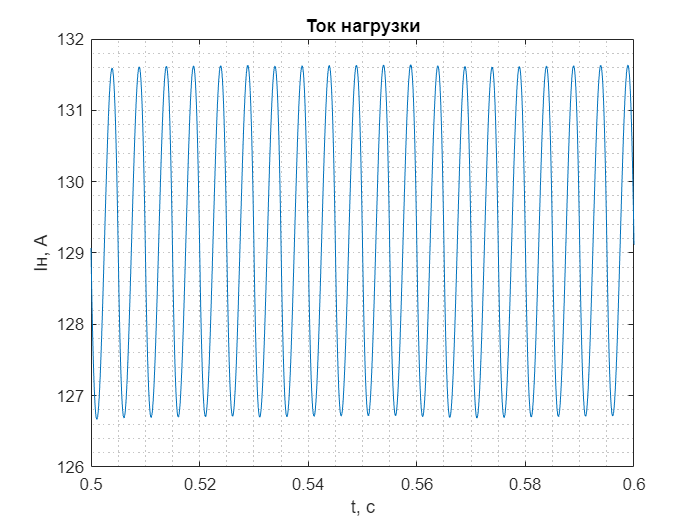


plot(ScopeACRL{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iн, А');
title('Ток нагрузки');
xlim([0.5 0.6]);

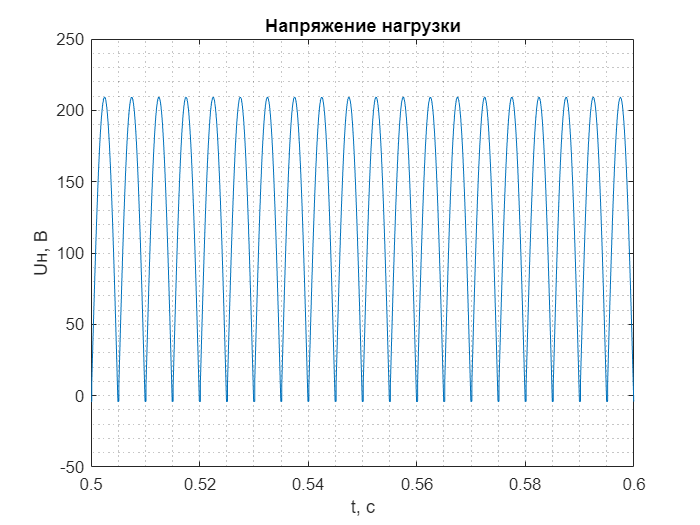


plot(ScopeACRL{3}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uн, В');
title('Напряжение нагрузки');
xlim([0.5 0.6]);

Осцилограммы напряжения и тока диодного моста (для сопротивления нагрузки 1 Ом) :

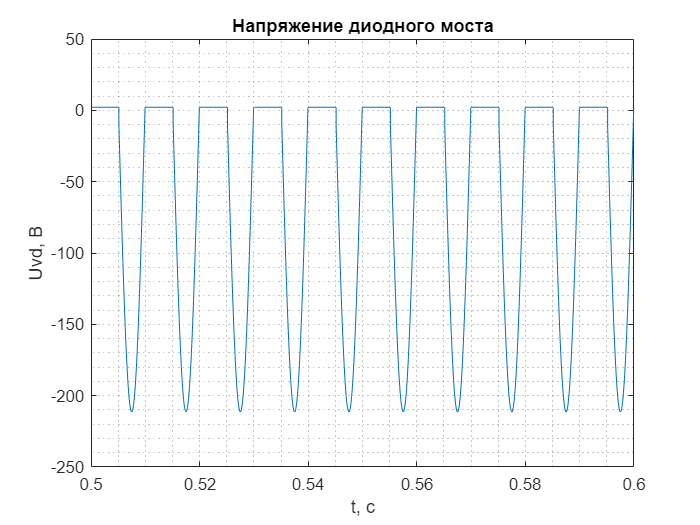

for R = 1
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeVD{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uvd, В');
title('Напряжение диодного моста');
xlim([0.5 0.6]);
end

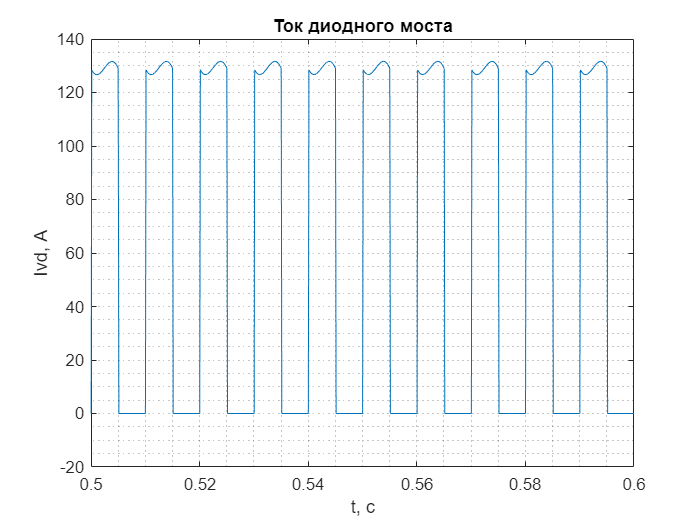

plot(ScopeVD{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Ivd, А');
title('Ток диодного моста');
xlim([0.5 0.6]);

Осцилограммы тока питания, нагрузки и напряжения на нагрузке (для сопротивления нагрузки 5 Ом) :

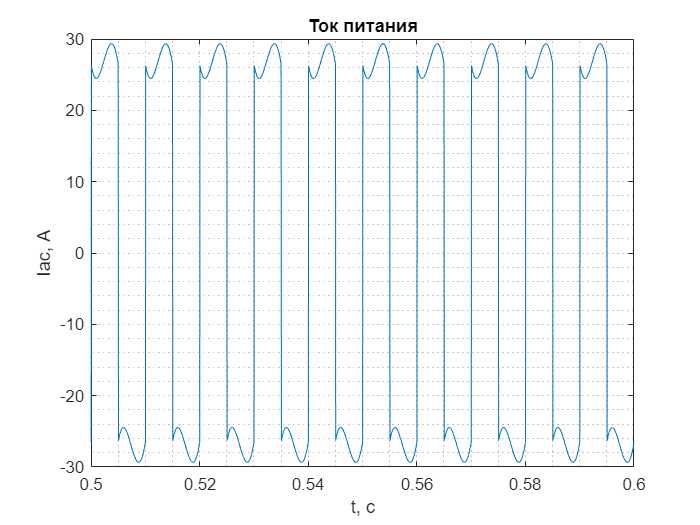

for R = 5
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeACRL{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iac, А');
title('Ток питания');
xlim([0.5 0.6]);
end

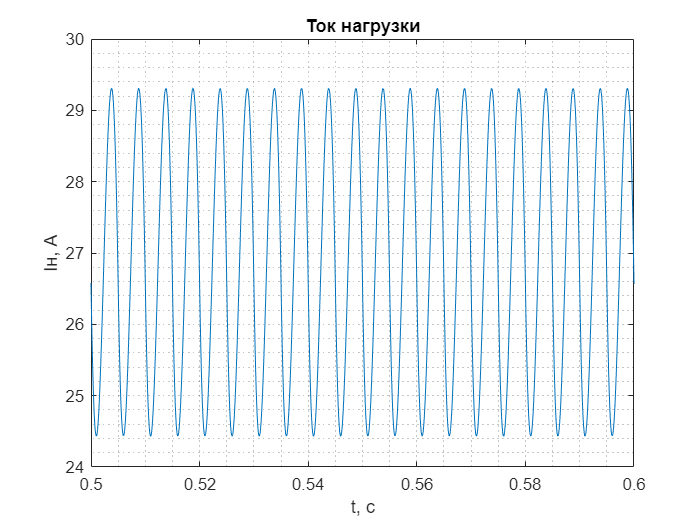

plot(ScopeACRL{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iн, А');
title('Ток нагрузки');
xlim([0.5 0.6]);

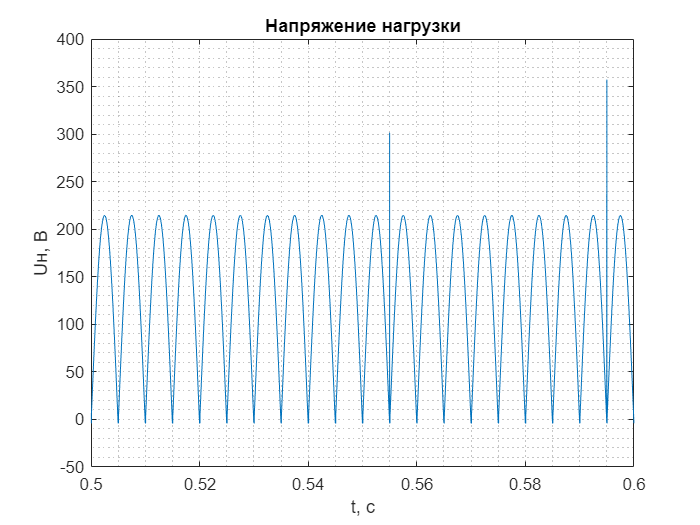

plot(ScopeACRL{3}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uн, В');
title('Напряжение нагрузки');
xlim([0.5 0.6]);

Осцилограммы напряжения и тока диодного моста (для сопротивления нагрузки 5 Ом) :

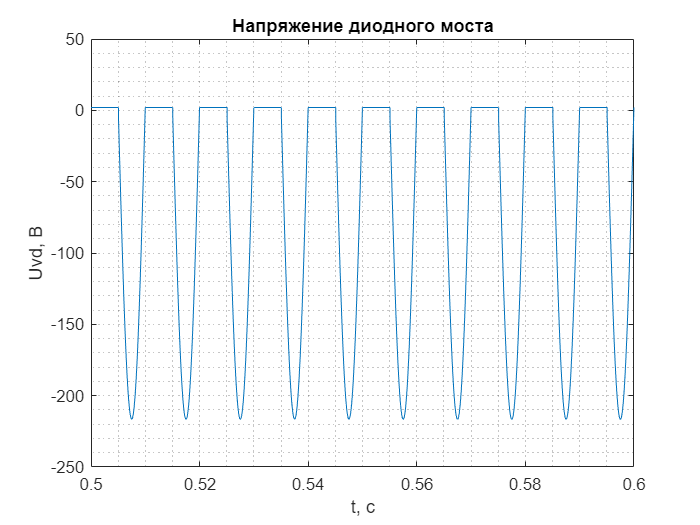

for R = 5
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeVD{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uvd, В');
title('Напряжение диодного моста');
xlim([0.5 0.6]);
end

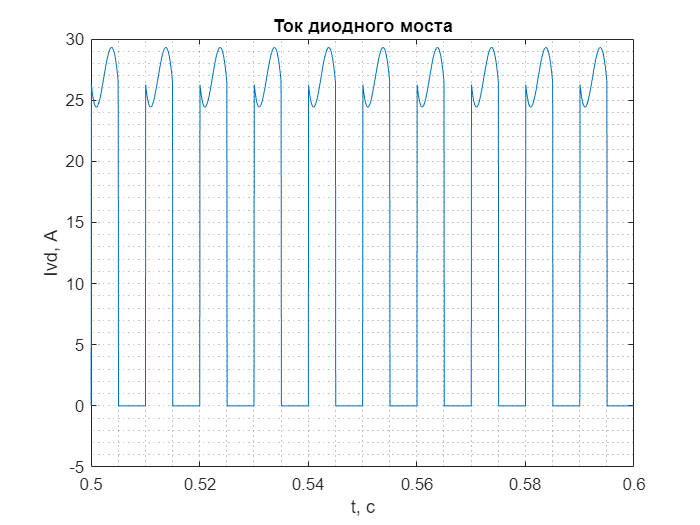

plot(ScopeVD{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Ivd, А');
title('Ток диодного моста');
xlim([0.5 0.6]);

Осцилограммы тока питания, нагрузки и напряжения на нагрузке (для сопротивления нагрузки 10 Ом) :

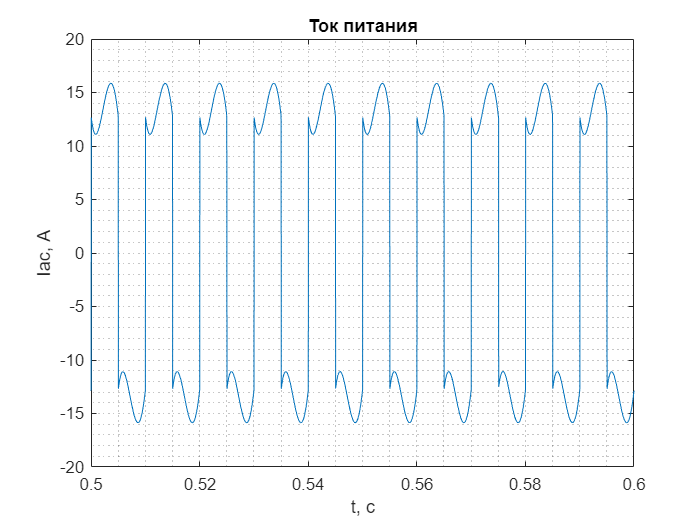

for R = 10
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeACRL{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iac, А');
title('Ток питания');
xlim([0.5 0.6]);
end

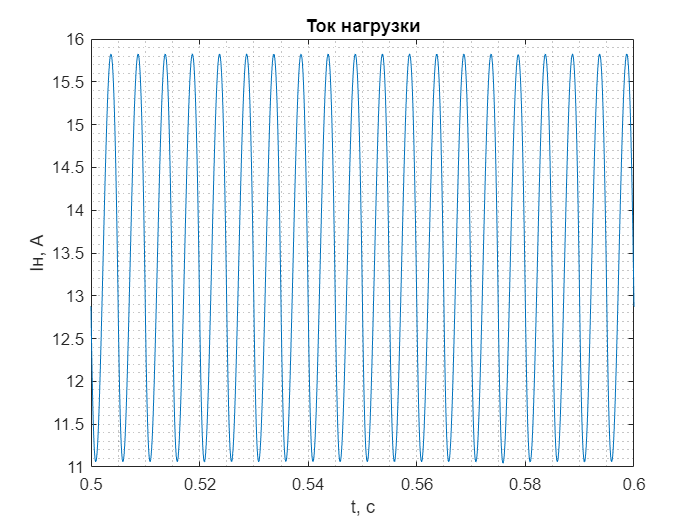

plot(ScopeACRL{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Iн, А');
title('Ток нагрузки');
xlim([0.5 0.6]);

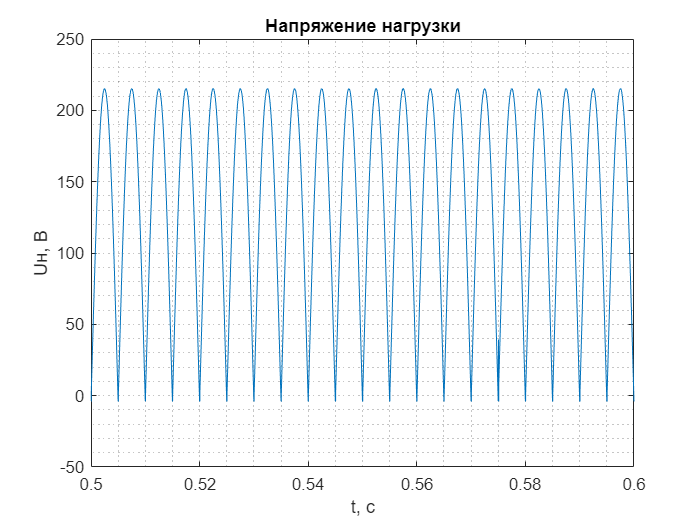

plot(ScopeACRL{3}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uн, В');
title('Напряжение нагрузки');
xlim([0.5 0.6]);

Осцилограммы напряжения и тока диодного моста (для сопротивления нагрузки 10 Ом) :

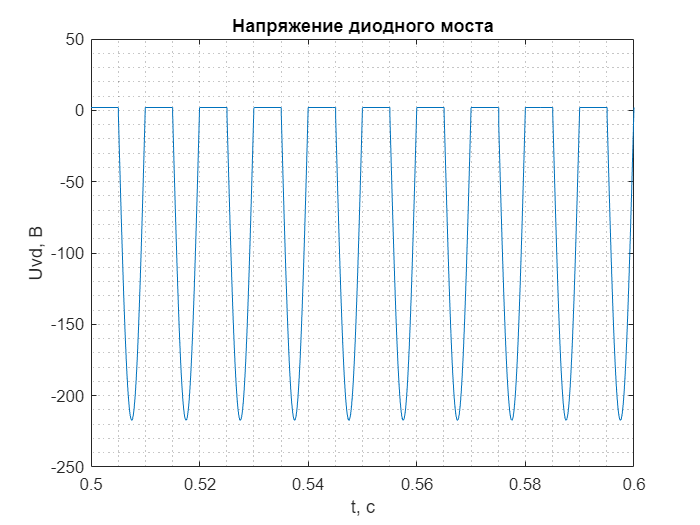

for R = 10
    load.Res = R;
    sim('lab1dulepovMinina2');
plot(ScopeVD{1}.Values);
grid("minor");
xlabel('t, с');
ylabel('Uvd, В');
title('Напряжение диодного моста');
xlim([0.5 0.6]);
end

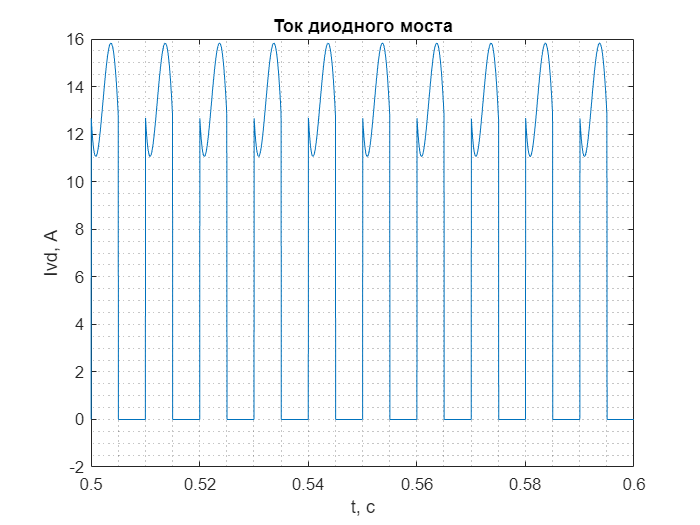

plot(ScopeVD{2}.Values);
grid("minor");
xlabel('t, с');
ylabel('Ivd, А');
title('Ток диодного моста');
xlim([0.5 0.6]);

8. Далее производим построение нагрузочной и энергетических характеристик согласно расчетной таблицы

Построение нагрузочной характеристики:

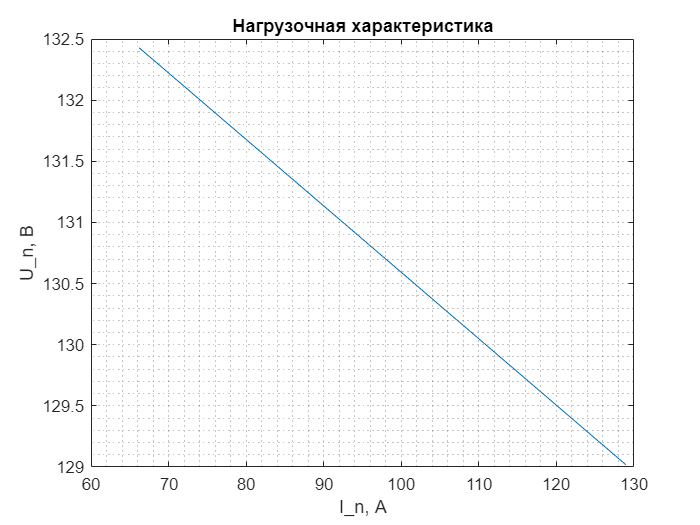

x = I_n (1:1:2);
y = U_n(1:1:2);
plot(x,y)
grid("minor");
xlabel('I_n, А');
ylabel('U_n, В');
title('Нагрузочная характеристика');

Построение энергетических характеристик:

x1 = I_n (1:1:10);

Index exceeds the number of array elements. Index must not exceed 3.

y1 = S_1(1:1:10);
x2 = I_n (1:1:10);
y2 = P_1(1:1:10);
x3 = I_n (1:1:10);
y3 = P_n(1:1:10);
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('U_n, В');
title('Энергетические характеристики');
legend('S_1','P_1','P_n');
legend("Position",[0.75702,0.15698,0.11679,0.16048])

9. Вывод:

    В ходе лабораторной работы мы исследовали работу однофазного неуправляемого двухполупериодного выпрямителя при работе на активно-индуктивную нагрузку. 

    При повышении сопротивления и индуктивности нагрузки: 

- ток нагрузки уменьшается; 

- напряжение нагрузки увеличивается;

- амплитуда первой гармоники тока в источнике питания уменьшается;

- начальная фаза гармоники тока в источнике питания уменьшается;

- напряжение на выпрямителе остается неизменным;

- ток выпрямителя уменьшается;

- полная мощность, потребляемая выпрямителем от источника питания уменьшается;

- активная мощность, потребляемая выпрямителем от источника питания уменьшается;

- мощность в нагрузке умеьшается.